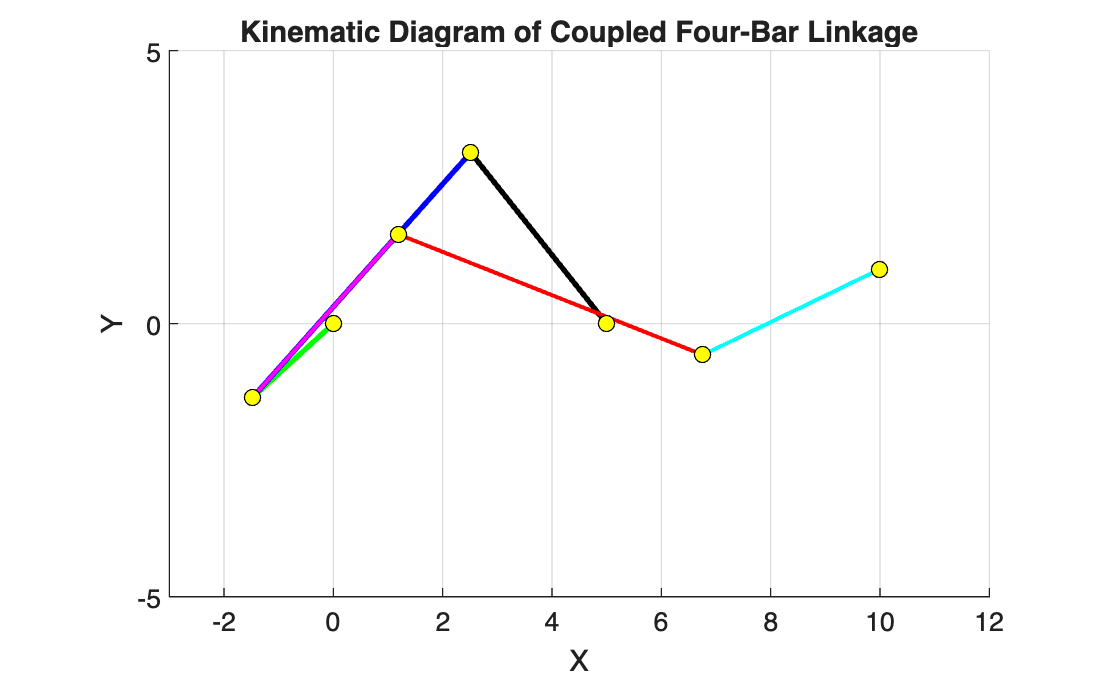

clc; clear; close all;

% ==============================
% Main script
% ==============================
drawframe_kinematic(1);     % Initial setup
for k = 1:200               % Animate
    drawframe_kinematic(2);
    pause(0.04);
end


% ==============================
% Function section
% ==============================
function drawframe_kinematic(f)
    persistent L1 L2 L3 L4 L5 L6 L7 L8 t2 t3 t4 t5 t6 f1 f2 hLinks hJoints

    if nargin < 1
        error('Not enough input arguments.');
    end

    if f==1
        % --- Figure setup ---
        clf; figure(1); hold on; axis equal;
        title('Kinematic Diagram of Coupled Four-Bar Linkage');
        xlabel('X'); ylabel('Y'); grid on;

        % --- Link lengths ---
        L1=5; L2=2; L3=6; L4=4; L5=6; L6=4; L7=5; L8=1;

        % --- Constraint equations ---
        f1 = @(t2,t)(L2*cos(t2)-(L1+L4*cos(t)))^2+(L2*sin(t2)-L4*sin(t))^2-L3^2;
        f2 = @(x5,y5,T)[x5+L5*cos(T(1))-(L1+L7+0.9*L6*cos(T(2)));
                        y5+L5*sin(T(1))-(L8+0.9*L6*sin(T(2)))];

        % --- Initial angles ---
        t4=acos(((L2+L3)^2-L1^2-L4^2)/(2*L1*L4));
        t2=asin(sin(t4*L4/(L2+L3)));
        c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);

        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);

        % --- Solve t5, t6 ---
        opts = optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[1.5*pi;1.5*pi],opts);
        t5=t56(1); t6=t56(2);

        % --- Define points ---
        A = [0,0]; 
        B = [L1,0]; 
        F = [L1+L7, L8];
        C = [x3,y3]; 
        D = [L1+L4*c4, L4*s4]; 
        E = [x5,y5]; 
        G = [L1+L7+0.9*L6*cos(t6), L8+0.9*L6*sin(t6)];

        % --- Draw links ---
        hLinks(1)=plot([A(1) C(1)], [A(2) C(2)], 'g', 'LineWidth', 2); % L2
        hLinks(2)=plot([C(1) D(1)], [C(2) D(2)], 'b', 'LineWidth', 2); % L3
        hLinks(3)=plot([B(1) D(1)], [B(2) D(2)], 'k', 'LineWidth', 2); % L4
        hLinks(4)=plot([C(1) E(1)], [C(2) E(2)], 'm', 'LineWidth', 1.5); % L5
        hLinks(5)=plot([E(1) G(1)], [E(2) G(2)], 'r', 'LineWidth', 1.5); % L6
        hLinks(6)=plot([G(1) F(1)], [G(2) F(2)], 'c', 'LineWidth', 1.5); % Ground part

        % --- Plot joints ---
        Pts = [A; B; C; D; E; G; F];
        hJoints = plot(Pts(:,1), Pts(:,2), 'ko', 'MarkerFaceColor','y', 'MarkerSize',6);

        axis([-3 12 -5 5]);
        drawnow;

    else
        % --- Update geometry ---
        t2=t2+2*pi/48;
        c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        t4=fzero(@(t)f1(t2,t),t4);
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);

        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);

        opts = optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[t5;t6],opts);
        t5=t56(1); t6=t56(2);

        % --- Update points ---
        A = [0,0]; 
        B = [L1,0]; 
        C = [x3,y3]; 
        D = [L1+L4*c4, L4*s4]; 
        E = [x5,y5]; 
        G = [L1+L7+0.9*L6*cos(t6), L8+0.9*L6*sin(t6)]; 
        F = [L1+L7, L8];

        % --- Update links ---
        set(hLinks(1),'XData',[A(1) C(1)],'YData',[A(2) C(2)]);
        set(hLinks(2),'XData',[C(1) D(1)],'YData',[C(2) D(2)]);
        set(hLinks(3),'XData',[B(1) D(1)],'YData',[B(2) D(2)]);
        set(hLinks(4),'XData',[C(1) E(1)],'YData',[C(2) E(2)]);
        set(hLinks(5),'XData',[E(1) G(1)],'YData',[E(2) G(2)]);
        set(hLinks(6),'XData',[G(1) F(1)],'YData',[G(2) F(2)]);

        % --- Update joints ---
        Pts = [A; B; C; D; E; G; F];
        set(hJoints, 'XData', Pts(:,1), 'YData', Pts(:,2));

        drawnow;
    end
end
